# How to pass MATLAB (Python) data to Python (MATLAB) data

## **Verify Python Configuration**

p = pyenv;
if p.Status == "NotLoaded"
    r = py.math.sqrt(4);
    assert(r == 2);
end
p

p =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\Users\pharouim\AppData\Local\Programs\Python\Python39\pythonw.exe"
          Library: "C:\Users\pharouim\AppData\Local\Programs\Python\Python39\python39.dll"
             Home: "C:\Users\pharouim\AppData\Local\Programs\Python\Python39"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "17592"
      ProcessName: "MATLAB"


## 1. Native conversions

See [this documentation link](https://www.mathworks.com/help/matlab/matlab_external/passing-data-to-python.html) for a complete list of data type mapping

### a. String

strMATLAB = "Safran"

strMATLAB = "Safran"

strPython = py.str(strMATLAB)

strPython =   Python str with no properties.

    Safran


### b. MATLAB struct => Python dict

S = struct('Robert',357,'Mary',229,'Jack',391)

S = struct with fields:
    Robert: 357
      Mary: 229
      Jack: 391


studentID = py.dict(S)

studentID =   Python dict with no properties.

    {'Robert': 357.0, 'Mary': 229.0, 'Jack': 391.0}


ans = 1×4 string array
    "Name1"    "Name2"    "Name3"    "Name4"


### c. MATLAB uniformed cell arrays => direct transformation

c       = {rand, rand};
py_dict = py.str(c)

py_dict =   Python str with no properties.

    (0.08382137799693257, 0.22897696871681883)


### d. MATLAB mixed cell arrays => use cell2struct

c       = {rand, rand, "rand"};
s       = cell2struct(c, ["field1", "field2", "field3"], 2);
py_dict = py.dict(s)

py_dict =   Python dict with no properties.

    {'field1': 0.7481515928237095, 'field2': 0.45054159850249775, 'field3': 'rand'}


## 2. Community and custom conversions

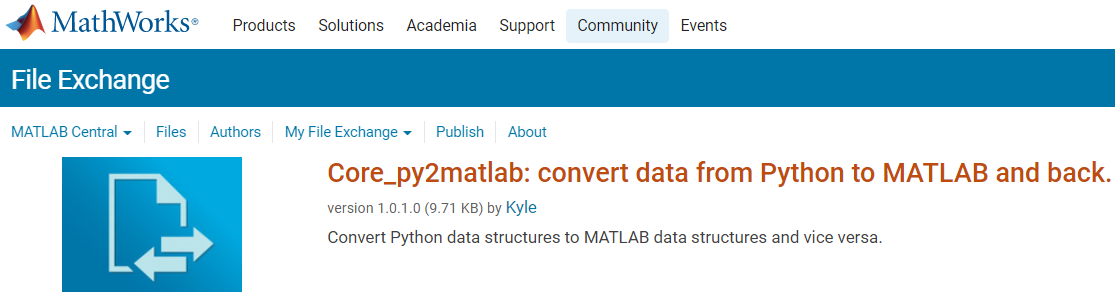

Use [Core_py2matlab and Core_matlab2py](https://www.mathworks.com/matlabcentral/fileexchange/53717-core_py2matlab-convert-data-from-python-to-matlab-and-back) functions from File Exchange to map and convert many data types from Pythonto MATLAB and back.

Use custom conversion like [table2dataframe](matlab:open('C:\Users\pharouim\OneDrive - MathWorks\ByProject\Events\Seminars_Masterclasses\Masterclasses\Masterclass_MATLAB_Simulink_And_Python_R2021b_for_Safran\table2dataframe.m')) function to convert MATLAB table to Pandas dataframe.

### **a. Convert MATLAB data to Python data with one function**

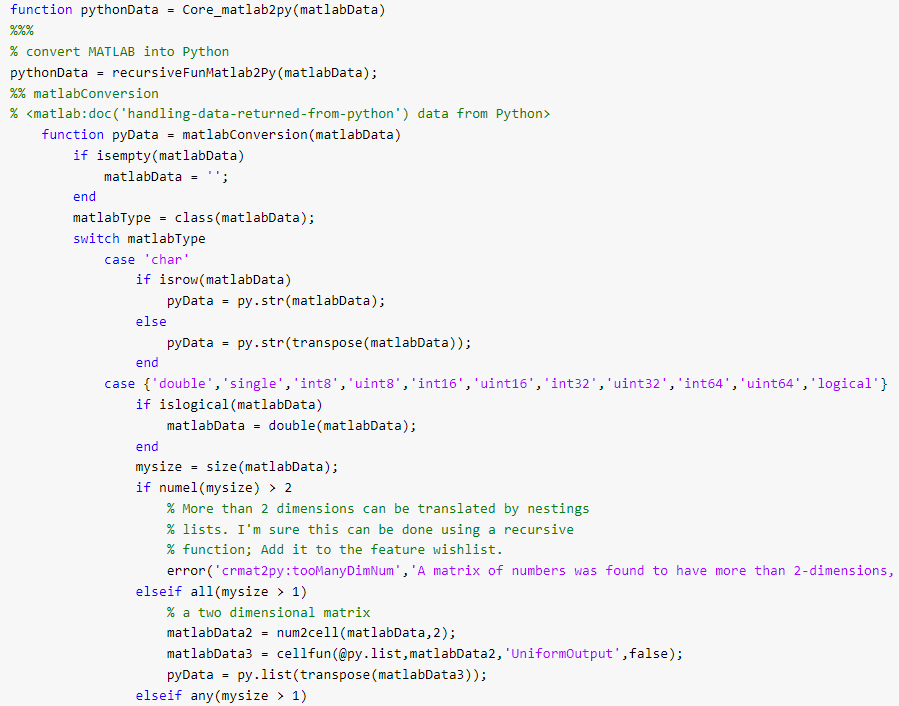

### b. Convert MATLAB table to Pandas dataframe

Custom function to pass table to dataframe

open table2dataframe.m

LastName      = {'Sanchez';'H';'Li';'Diaz';'Brown'};            % char
Name          = ["Pierre";"Heather";"Yann";"Mouba";"Michelle"]; % string
Age           = [38;43;38;40;49];                               % double
Smoker        = logical([1;0;1;0;1]);                           % logical
Cat           = categorical(["A";"B";"C";"D";"E"]);             % categorical
T             = table(LastName,Name,Age,Smoker,Cat)

T = 5×5 table
     LastName         Name       Age    Smoker    Cat
    ___________    __________    ___    ______    ___

    {'Sanchez'}    "Pierre"      38     true       A 
    {'H'      }    "Heather"     43     false      B 
    {'Li'     }    "Yann"        38     true       C 
    {'Diaz'   }    "Mouba"       40     false      D 
    {'Brown'  }    "Michelle"    49     true       E 


df = matlab.python.table2dataframe(T)

df =   Python DataFrame with properties:

          T: [1×1 py.pandas.core.frame.DataFrame]
         at: [1×1 py.pandas.core.indexing._AtIndexer]
      attrs: [1×1 py.dict]
       axes: [1×2 py.list]
    columns: [1×1 py.pandas.core.indexes.base.Index]
     dtypes: [1×1 py.pandas.core.series.Series]
      empty: 0
      flags: [1×1 py.pandas.core.flags.Flags]
        iat: [1×1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1×1 py.pandas.core.indexing._iLocIndexer]
      index: [1×1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1×1 py.pandas.core.indexing._LocIndexer]
       ndim: [1×1 py.int]
      shape: [1×2 py.tuple]
       size: [1×1 py.numpy.int32]
      style: [1×1 py.pandas.io.formats.style.Styler]
     values: [1×1 py.numpy.ndarray]

      LastName      Name   Age  Smoker Cat
    0  Sanchez    Pierre  38.0     1.0   A
    1        H   Heather  43.0     0.0   B
    2       Li     

hello
